## Exercise 1: Moving Average filter

### 10 Taps

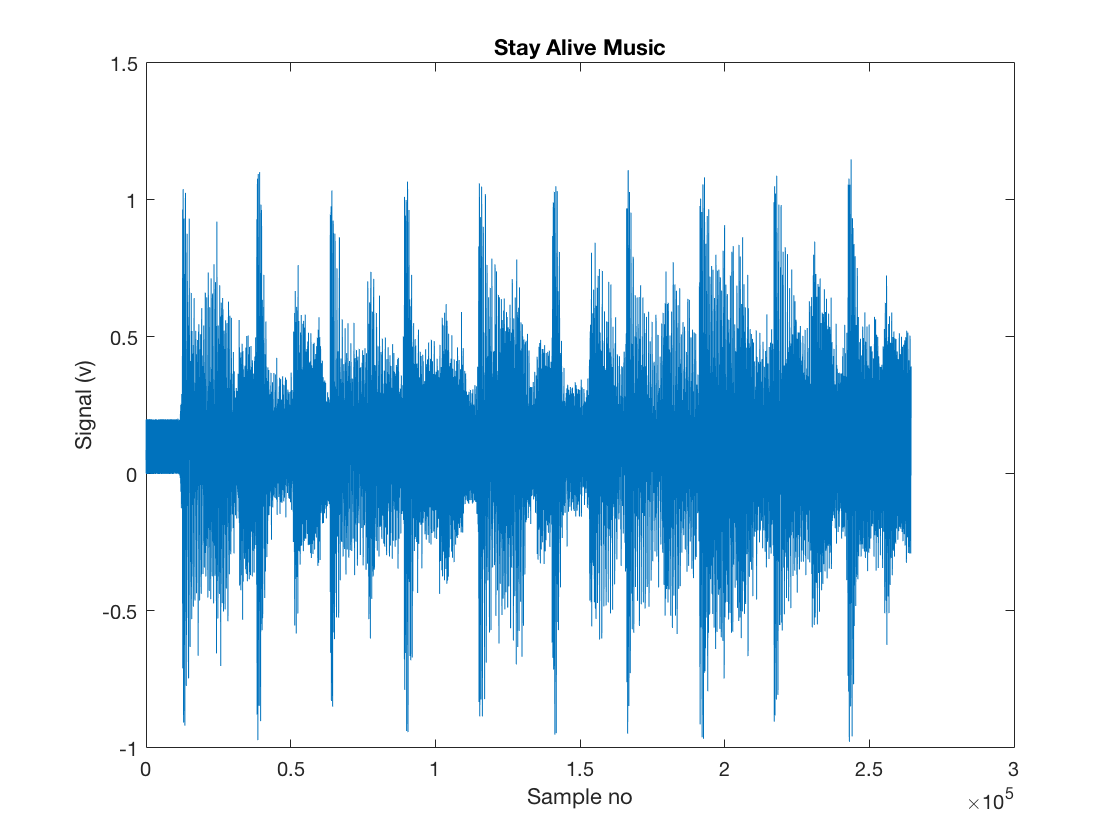

% Lab 5 - Ex 5a: 4-taps Movng average filter
% The inefficient way
clear all
[sig fs] = audioread('bgs.wav');
% Add noise to music
x = sig + 0.2*rand(size(sig));
% Plot the signal
figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');

% Filter music with moving average filter
N = size(x);
for i=4:N
    y(i) = (x(i) + x(i-1) + x(i-2) + x(i-3)) / 4;
end
y(1) = x(1) / 4;
y(2) = (x(2) + x(1)) / 4;
y(3) = (x(3) + x(2) + x(1)) / 4;
% Play the origional & then the filtered sound
sound(x, fs)
disp('Playing the original - press return when finished')

Playing the original - press return when finished


sound(y, fs)
disp('Playing the filter music')

Playing the filter music


### 20 Taps

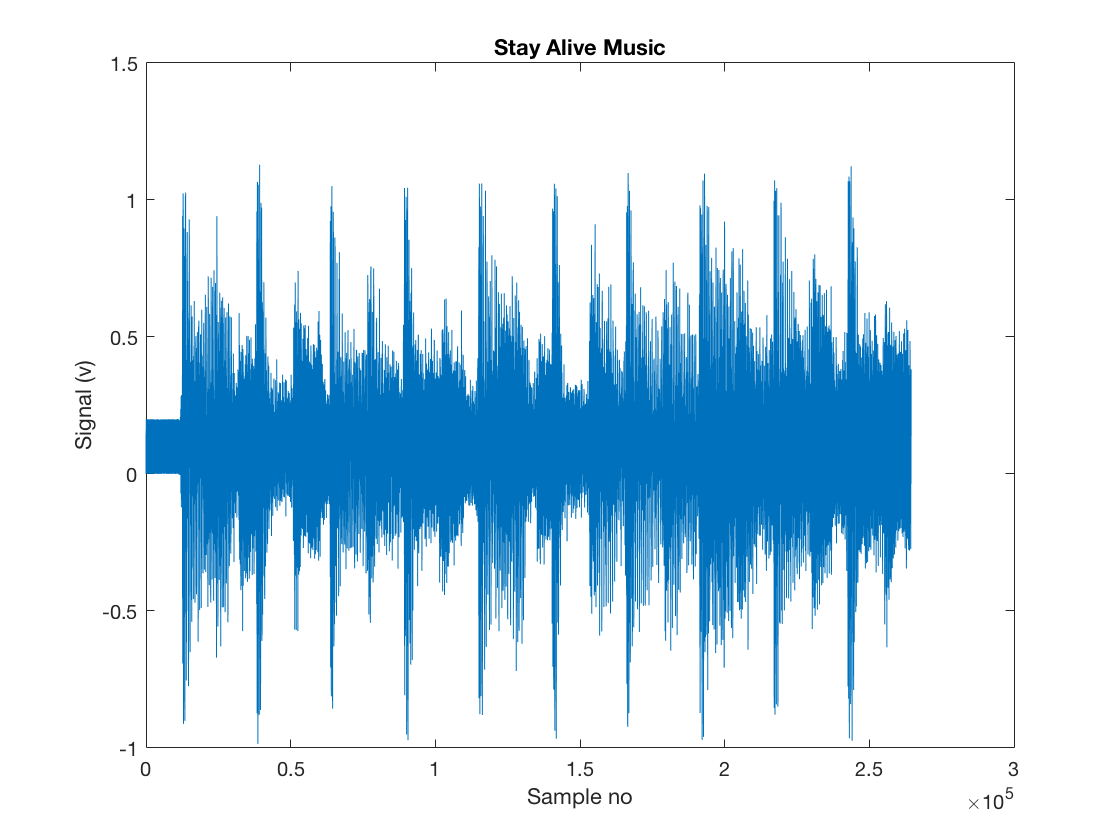

% Lab 5 - Ex 5a: 4-taps Movng average filter
% The inefficient way
clear all
[sig fs] = audioread('bgs.wav');
% Add noise to music
x = sig + 0.2*rand(size(sig));
% Plot the signal
figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');

% Filter music with moving average filter
N = size(x);
N_tap = 10
for i = 1:N
    y(i) = 0
    if i < N_tap:
        for n = 0:i - 1
            y(i) = y(i) + x(i - n)
        end
        y(i) = y(i) / N_tap;
    else
        for n = 0:N_tap - 1
            y(i) = y(i) + x(i - n)
        end
        y(i) = y(i) / N_tap;
    end
        
    
end
y(1) = x(1) / 4;
y(2) = (x(2) + x(1)) / 4;
y(3) = (x(3) + x(2) + x(1)) / 4;
% Play the origional & then the filtered sound
sound(x, fs)
disp('Playing the original - press return when finished')

Playing the original - press return when finished


sound(y, fs)
disp('Playing the filter music')

Playing the filter music
